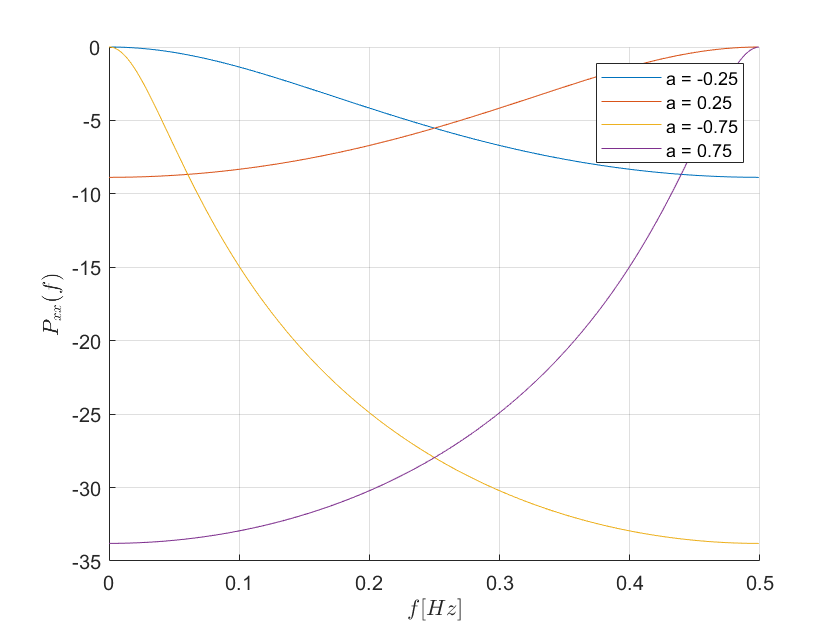

  clear all;
  close all;
  
  a = [-0.25 0.25 -0.75 0.75];
  
  b = [1];
  
  
  figure;
  hold on;
  leg = {};
  for k = 1:length(a)
      A = [1 a(k)];
      B = b;
      [H, w] = freqz(B, A);
      pxx = abs(H).^2;
      plot(w/2/pi, 20*log10(pxx/max(pxx)));
      leg{k} = ['a = ' num2str(a(k))];
  end
  
  xlabel('$f[Hz]$','Interpreter','latex');
  ylabel('$P_{xx}(f)$','Interpreter','latex');
  grid on;
  legend(leg);

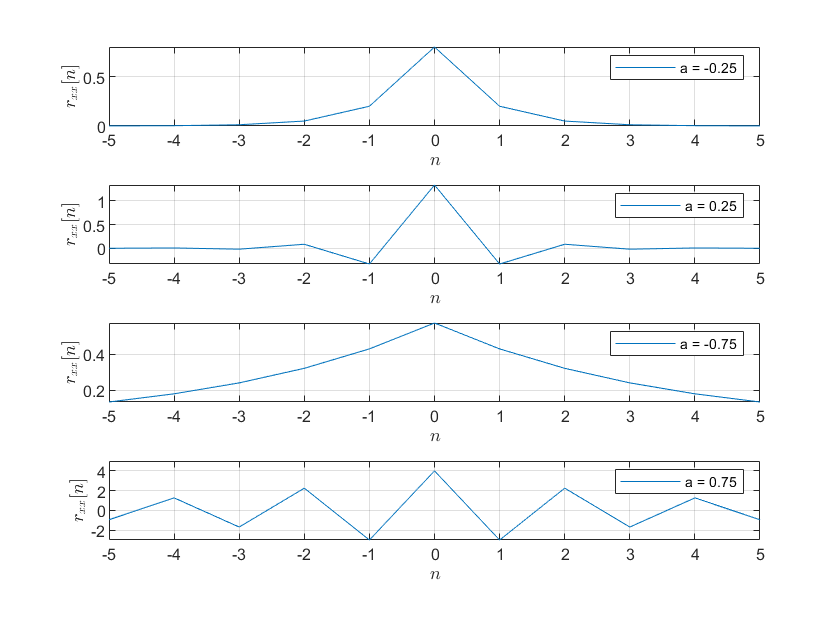

n = -5:5;
rxx = zeros(1, length(n));

figure;


for k = 1:length(a)
    subplot(4, 1, k)
    rxx = 1/(1-a(k))*(-a(k)).^(abs(n));
    plot(n, rxx);
    xlabel('$n$','Interpreter','latex');
    ylabel('$r_{xx}[n]$','Interpreter','latex');
    grid on;
    legend(['a = ' num2str(a(k))]);
end

clear all;
close all

rho = 0.5;
w = [pi/4 pi/2 3*pi/4]

w =     0.7854    1.5708    2.3562


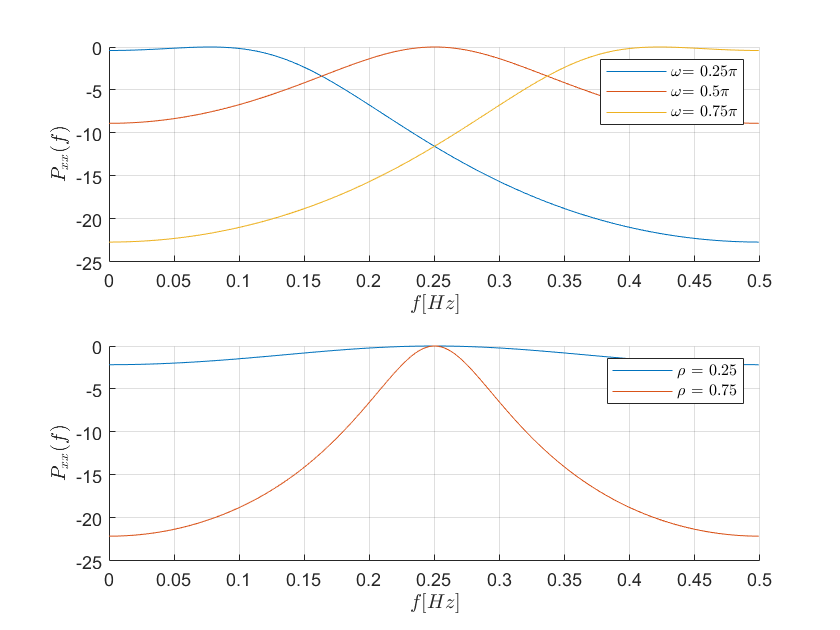

figure;
subplot(2, 1, 1)
hold on;
leg = {};
for k = 1 : length(w)
    A = [1, -2*cos(w(k))*rho, rho^2];
    B = [1];
    [H, W] = freqz(B, A);
    pxx = abs(H).^2;
    plot(W/2/pi, 20*log10(pxx/max(pxx)));
    leg{k} = [' $\omega $= ' num2str(w(k)/pi) '$\pi$'];
end

  xlabel('$f[Hz]$','Interpreter','latex');
  ylabel('$P_{xx}(f)$','Interpreter','latex');
  grid on;
  legend(leg,'Interpreter','latex');
  
  rho = [0.25 0.75];
  w= pi/2;
  
subplot(2, 1, 2)
hold on;
leg = {};
for k = 1 : length(rho)
    A = [1, -2*cos(w)*rho(k), rho(k)^2];
    B = [1];
    [H, W] = freqz(B, A);
    pxx = abs(H).^2;
    plot(W/2/pi, 20*log10(pxx/max(pxx)));
    leg{k} = [' $\rho$ = ' num2str(rho(k))];
end

  xlabel('$f[Hz]$','Interpreter','latex');
  ylabel('$P_{xx}(f)$','Interpreter','latex');
  grid on;
  legend(leg,'Interpreter','latex');

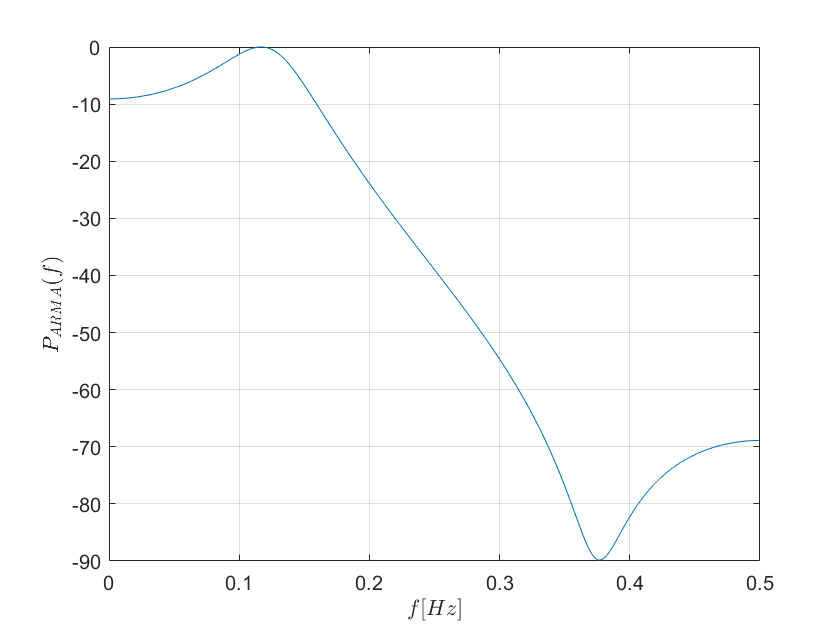

clear all;
close all
figure;
  A = [1, -2*cos(-pi/4)*0.8, 0.8^2];
  B = [1, -2*cos(3*pi/4)*0.9, 0.9^2];
      [H, W] = freqz(B, A);
    pxx = abs(H).^2;
    plot(W/2/pi, 20*log10(pxx/max(pxx)));

    
    
  xlabel('$f[Hz]$','Interpreter','latex');
  ylabel('$P_{ARMA}(f)$','Interpreter','latex');
  grid on;

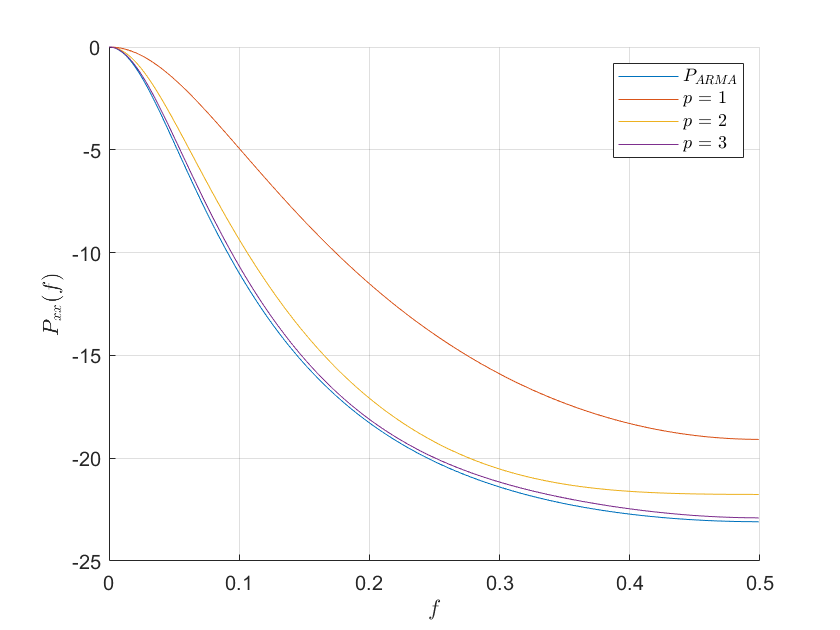

clear all;
close all;

a = -0.7;
b = -0.2;

A = [1 a];
B = [1 b];

[H,W] = freqz(B, A);
pxx= abs(H).^2;

figure;
hold on;
plot(W/2/pi, 20*log10(pxx/max(pxx)));
leg{1} = ['$P_{ARMA}$'];

c = ones(1, 4);
k = 1:3;

c(2:4) = (a-b)*(-b).^(k-1);

for k = 1 : 3
    
    A = c(1 : k+1);
    B = [1];
    [H,W] = freqz(B, A);
    
    pxx= abs(H).^2;


hold on;
plot(W/2/pi, 20*log10(pxx/max(pxx)));
    
    leg{k+1} = [' $p$ = ' num2str(k)];
end

  xlabel('$f$','Interpreter','latex');
  ylabel('$P_{xx}(f)$','Interpreter','latex');
  grid on;
  legend(leg,'Interpreter','latex');